clear
clc

# Estimating Outcomes in Annual- Perennial Model 

The fundamental quantities to estimate are

- $\lambda_i$ for each species, which depends only on demography,

- $\alpha_i$ for each species, which we infer based on total population size

- $b_i$, which depends on the biomass of plants and how much litter released

- $L^*$, the estimates of tolerance to litter.

Each are estimated in seperate sections below.

## Estimating $\lambda$

The reproductive number for the annual is

    $\lambda_A = \frac{g_Ae_Ay_A}{1-s_A(1-g_A)}$.

We have the following estimates from the literature (and their sources):

sA = 0.15; % Redwood et al. (2018);  
gA = 0.79;  yA = [6000 7000]; % Wilson et al. (2015)
eA = [0.53 0.96]; % Emery et al. (2013); Warren et al. (2013)

There is uncertainty in the basic reproductive number because we have a range of values for *y**A* and *e**A*. One way to characterize this uncertainty is by the minimum, median, and maximum values of the distribution. 

lambdaA_median = mean(yA)*gA*mean(eA)/(1 - sA*(1-gA));

lambdaA = 	1.0e+03 *

    2.5939    3.9500    5.4815


lambdaA_minmax = yA*gA.*eA/(1 - sA*(1-gA));
lambdaA = [lambdaA_minmax(1),lambdaA_median, lambdaA_minmax(2)]

The reproductive number for the perennial is 

    $\lambda_P = \frac{g_Pe_Py_P}{1-s_P(1-g_P)}\left(f + \frac{p_1}{1-p_2} \right)$.

We have the following estimates from the literature (and their sources), with indication whether the value was from a species in the genus *Elymus* or from another perennial species:

sP = 0.05; gP = 0.8; % Garrison and Stier (2010)  *Elymus value
yP = [390,435];  % Stevens (1957) *Elymus value
p2 = [0.8,0.97]; eP = [0.3,0.51]; % Lauenroth and Adler (2008) *Non-Elymus grass
f = 0; p1 = p2; % Both assumed.

Again, we will calculate the minimum, median, and maximum values of lambda.

lambdaP_minmax = gP.*yP.*eP.*(f + fliplr(p1)./(1-fliplr(p2)))./(1 - fliplr(sP).*(1-gP));

lambdaP = 	1.0e+03 *

    3.0570    1.0389    0.7171


lambdaP_median = mean(gP)*mean(yP)*mean(eP)*(mean(p1)/(1-mean(p2)))/(1 - mean(sP)*(1-mean(gP)));
lambdaP = [lambdaP_minmax(1), lambdaP_median, lambdaP_minmax(2)]

Using these distributions of $\lambda$s, who is the dominant competitor in the absence of litter? 

The ratio's of reproductive numbers give an indication of who is dominant. 

lambda_ratio = lambdaA'./lambdaP

lambda_ratio =     0.8485    2.4968    3.6173
    1.2921    3.8021    5.5084
    1.7931    5.2762    7.6440


Here is a plot of the range of estimates of lambda for each species.

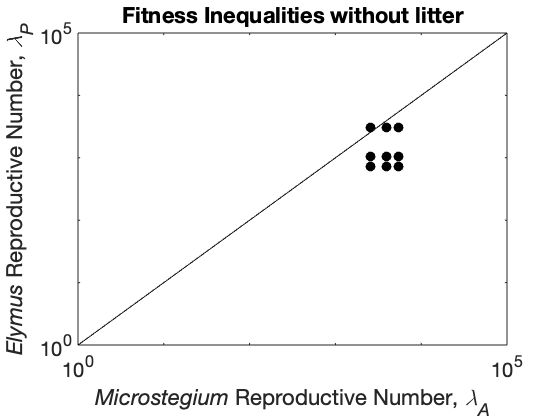

lambda_max = max([lambdaA, lambdaP]);
loglog([1,20*lambda_max], [1,20*lambda_max], 'color', 'black');
hold on
for i = 1:length(lambdaA)
    scatter(lambdaA(i)*ones(1,length(lambdaP)), lambdaP,...
        100, 'filled', 'CData', zeros(1,3))
end
hold off
xlabel('{\itMicrostegium} Reproductive Number, {\it\lambda_A}');
ylabel('{\itElymus} Reproductive Number, {\it\lambda_P}')
set(gca, 'FontSize', 20);
title('Fitness Inequalities without litter')
axis([1, 10^5, 1, 10^5])

It looks here like most of our evidence suggests that *Microstegium* is a better competitor than *Elymus*, which fits with our prior expectations.

## Comparing Densities Expected in Monoculture

The next step is to calculate the values of *α*. The value of *α* in the model is presented as a per-capita effect, which can be estimated using competition experiments. However, these are very sensitive to the scale of the experiments and the densities of the plants used. That said, *α *has the only practical role in the model of scaling equilibrium plant density. It plays almost no role in coexistence of species, except indirectly through litter production. Instead of calculating these directly, we use estimates of population density in nature to fit values of *α. *

The equilibrium density of plants is 

    $g_A\hat{E}_A\hat{N}_A =  \frac{\lambda_A - 1}{\alpha_A}$.

It thus suffices that *α**A* can be estimated with *λ**A*and the equilibrium plant density (i.e., the right-hand side of the equation directly above). An estimate of *α**A* is 

    $\alpha_A = \text{exp}\left \{ \text{ln}[\lambda_A - 1] - \overline{\text{ln}[\text{plant density}]} \right \}$.

where an overbar is a simple average. We don't have data on plant densities, but we have biomass densities. Kerry Stricker and Luke Flory (unpublished) measured densities of *Microstegium* biomass in 25cm x 25cm plots across *Microstegium*’s invaded range. To get a reasonable estimate of equilibrium density of *Microstegium *in the absence of litter, we chose plots with less than 0.5g of litter (n = 17) in these plots and calculate the average log biomass of *Microstegium.* The average ln density in these plots is

ln_micro_biomass_density = 4.17; % units: log(grams/m^2)

To get to individual density, we need an estimate of individual biomass. Wilson et al. (2016) measure individual biomass in a field experiment. The average ln individual biomass from that study is

ln_micro_ind_biomass = 0.441; % units: log(grams/ind)

This means that the log density of plants is 

ln_micro_density = ln_micro_biomass_density - ln_micro_ind_biomass 

ln_micro_density = 3.7290

%units: log(inds/m^2).
micro_density = exp(ln_micro_density) %units: inds/m^2

micro_density = 41.6374

Hence, an estimate for *α**A* is

alphaA = (lambdaA - 1)/exp(ln_micro_density) 

alphaA =    62.2735   94.8425  131.6235


%units: m^2/inds;

Instead of using these estimates, we use the functional relationship between *α**A*and equilibrium plant to create the coexistence diagrams. This is because we need to create invasion boundaries as a function of *λ**A* and *λ**P*. Hence, the actual values of *α**A* change in those diagrams as *λ**A* is varied but plant density remains fixed. 

To do the same thing for *Elymus*, we first recognize that perennial adult density in monoculture equilibrium is 

    
$$\hat{N}_P = \frac{\lambda_P-1}{\alpha_P\prime}$$
 

and the total plant density is 

    $\hat{N}_P + g_P\hat{E}_P\hat{N}_S = \left[\frac{\lambda_P-1}{\alpha_P\prime}\right]\left[1 + \frac{1-p_2}{p_1}\right]$.

Again, we choose to use field observations of *Elymus*density. Field observations of cover of *Elymus *and *Microstegium* and found that *Elymus* cover in 4 replicate 1 quadrats was 23% cover of *Microstegium *(Amy E. Kendig, unpublished data).

ln_elymus_biomass_density = log(0.23) + ln_micro_biomass_density; 
% units:log(grams/m^2)

In greenhouse experiments, *Elymus *biomass is 2-3 times the biomass of *Microstegium *(Amy E. Kendig, unpublished data), So we set individual biomass of *Elymus *to be double the biomass of *Microstegium* and then estimated the corresponding $\alpha'_P$ values.

ln_elymus_ind_biomass = log(2) + ln_micro_ind_biomass; 
%units: log(grams/ind)

ln_elymus_density = ln_elymus_biomass_density - ln_elymus_ind_biomass

ln_elymus_density = 1.5662

%units: log(inds/m^2)
elymus_density = exp(ln_elymus_density) %units: inds/m^2

elymus_density = 4.7883

alphaPprime = (lambdaP_minmax - 1).*(1+(1-p2)./p1)/exp(ln_elymus_density)

alphaPprime =   797.7689  154.1752


%units: m^2/inds;

This also means that, in monoculture equilibrium, the relative density of *Elymus *to *Microstegium *is

plant_density_ratio = exp(ln_micro_density-ln_elymus_density)

plant_density_ratio = 8.6957

From these estimates, the monoculture equilibrium density of *Microstegium *is 3.45 inds/(25cm x 25cm) and the equilibrium monoculture density of *Elymus *is 0.4 indx/(25cm x 25cm), meaning that *Microstegium *is about 8.5 times more dense that *Elymus*on a per-individual basis and about 4 times more dense on a biomass basis. These estimates are broadly similar to field observations (Amy E. Kendig, personal observation). 

## Litter sensitivity and production

The final parameters to estimate are sensitivity to litter  and litter production values . Estimating *b**A* is straightforward since it is simply aboveground biomass. Wilson et al (2016) report from their field experiment that average biomass is 5.6 g/ind (note that this differs from the average on the ln scale, which was appropriate above in estimating the competition coefficients). DeMeester and Richter (2010) estimate that 89% of this biomass is retained from the end of the growing season to the beginning of the following growing season Hence, *b**A* is 

average_micro_biomass = 5.6; %units: grams
biomass_retention = 0.89;
bA = average_micro_biomass*biomass_retention % units: grams

bA = 4.9840

For the perennial, we again assume that *Elymus *biomass is double *Microstegium*'s biomass, but note that in a greenhouse experiment, 55% of *Elymus *biomass was dead at the end of the growing season (Amy E. Kendig, unpublished data). 

Elymus_Micro_biomass_ratio = 2;
Elymus_Dead_Biomass_Fraction = 0.55;

Under the assumption that all this dead material is deposited as litter (i.e., none remains on the plant), we have the following value for *Elymus *litter production:

bP = biomass_retention*Elymus_Micro_biomass_ratio*...
    Elymus_Dead_Biomass_Fraction*average_micro_biomass %units: grams

bP = 5.4824

We used to two experimental studies of litter addition and removal to estimate $\beta$ for each species. 

To estimate the effects of litter on *M. vimineum* establishment, we used data from the study by Warren et al. (2013). Six blocks containing six plots each were established in a forest in North Carolina, USA in September 2009. Each plot was a 10-cm diameter PVC collar (0.0079 m2) and was assigned to one of three litter treatments: bare soil, decomposed leaf litter (~ 1 cm depth), and decomposed leaf litter plus 5 cm of the current year’s leaf litter.  To convert litter depth to density, we used values from the study by Ash (1995). Litter dry mass and litter depth were measured at four locations and two time points (eight replicates, 0.25 m2 each) in a forest in North Carolina and the average values for each location-time combination were reported. There was not a strong linear relationship between litter weight and litter depth (LM: R2= 0.015), but the average litter depth was 4.95 cm and the average litter weight was 603 g m2. We used this value to convert litter depth values to litter density as follows

litter_depths = [1,5];
litter_densities = litter_depths*(603/5) %units of g/m2

litter_densities =   120.6000  603.0000


Sixteen *M. vimineum* seeds were placed in each plot, either on the bare soil or, if present, on the decomposed litter. Half of the plots were watered with drip irrigation during the following growing season and the other half were not. The number of seedlings were counted in May 2010 and seedling survival was assessed in October 2010. We extracted the percentage of seedlings surviving in non-watered plots with no litter and with litter (Fig. 2): 

E_Lequaltozero = 0.96;
seedling_survival = [0.69, 0.08];

We took the values of germination without litter as $e_A$ and used the largest litter treatment to fit $\beta_A$ using the relationship

$\text{ln}\beta_A = \overline{\text{ln}\left\{ \frac{e_A}{E_A(L)} - 1 \right \}} - \overline{\text{ln}L}$        (1)

where the overbar is the simple average.  

ln_betaA = log((E_Lequaltozero./seedling_survival - 1)) - log(litter_densities);
betaA = exp(mean(ln_betaA))

betaA = 0.0077

#### Perennial

For estimating $\beta_P$, we could find no experiments of litter on establishment for *Elymus*, so instead we used results from the study by Reynolds et al. (2001). Seeds of *Nasella pulchra*, *Festuca rubra*, *Calamagrostis nutkaensis*, and *Deschampsia caespitosa* ssp.* Holciformis* were planted in three 1 m x 1.5 m plots in October 1999 in a grassland in California, USA. The plots had been cleared of background vegetation in the preceding two years and were assigned one of three litter treatments: bare soil, 200 g *Holcus lanatus* litter (133 g m2), or 450 g *H. lanatus* litter  (300 g m2). Each plot contained six subplots per species, which were planted with 30 seeds each. Seedlings were counted four, six, and ten weeks post planting and the maximum number were presented in figures. We extracted the proportion of seeds germinated for each species for the bare soil and high litter treatment (Fig. 1) and calculated $\beta_P$. Note that the proportion germinated data includes both germination and establishment, as we define them.

litter_densities = [133, 300]; %units: g/m^2
eP_est = 0.51; % establishment at zero litter density
establishment = [0.31, 0.28]

establishment =     0.3100    0.2800


We estimated $\beta_P$ using this data just as we did with $\beta_A$ using equation (1).

ln_betaP = log((eP_est./establishment - 1)) - log(litter_densities);
betaP = exp(mean(ln_betaP))

betaP = 0.0036

Now we can calculate L*s for the species

LstarA = (lambdaA - 1)/betaA

LstarA = 	1.0e+05 *

    3.3703    5.1329    7.1235


LstarP = (lambdaP - 1)/betaP

LstarP = 	1.0e+05 *

    8.3853    2.8479    1.9649


The ratio of litter sensitivities is 

beta_ratio = betaA./betaP

beta_ratio = 2.1110

And L*s plotted against one another show that *Elymus *is, in general, a dominant competitor in the presence of litter. 

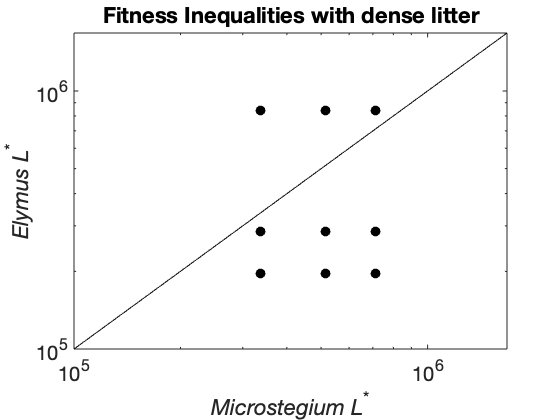

Lstar_max = max([LstarA, LstarP]);
loglog(2*[1,Lstar_max], 2*[1,Lstar_max], 'color', 'black');
hold on
for i = 1:length(LstarA)
    scatter(LstarA(i)*ones(1,length(LstarP)), LstarP,...
        100, 'filled', 'CData', zeros(1,3))
end
hold off
xlabel('{\itMicrostegium L}^*'); ylabel('{\itElymus L}^*')
set(gca, 'FontSize', 20); axis([100000,2*Lstar_max, 100000, 2*Lstar_max])

title('Fitness Inequalities with dense litter')

## Comparing Competitive Hierarchies and Litter Hierarchies

We can compare the competitive hirearchies both in the presence and absence of litter by plotting the ratio $L_A^*/L_P^*$ against $\lambda_A/\lambda_P$ on a log-scale. 

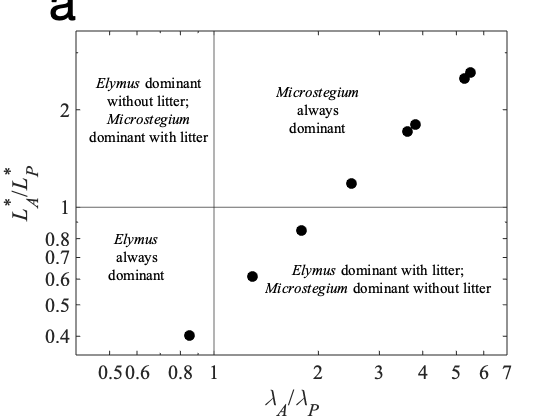

Lstar_ratio = ones(3,1)*LstarA./(LstarP'*ones(1,3));
Lambda_ratio = ones(3,1)*lambdaA./(lambdaP'*ones(1,3));
figure(1)
loglog(reshape(Lambda_ratio, 9, 1), reshape(Lstar_ratio, 9, 1),...
    'o', 'MarkerSize', 10, 'MarkerFaceColor', 'Black',...
    'MarkerEdgeColor','black');
axis([0.4,7,0.35,3.5])
xline(1); yline(1); ax = gca; ax.FontSize = 20;
xlabel('{\it\lambda_A}/{\it\lambda_P}')
ylabel('{\itL^*_A}/{\itL^*_P}');
set(gca,'FontName', 'Times New Roman')
t1 = text(3,0.6, {'{\itElymus} dominant with litter;',...
    '{\itMicrostegium} dominant without litter'},...
    'HorizontalAlignment',"center");
t2 = text(2,2, {'{\itMicrostegium}', 'always', 'dominant'},...
    'HorizontalAlignment',"center");
t3 = text(0.6,0.7, {'{\itElymus}','always','dominant'},...
    'HorizontalAlignment',"center");
t4 = text(0.65,2, {'{\itElymus} dominant', 'without litter;',...
    '{\itMicrostegium}', 'dominant with litter'},...
    'HorizontalAlignment',"center");
set([t1,t2,t3,t4], {'FontSize'}, {15})
set([t1,t2,t3,t4], {'FontName'}, {'Times New Roman'})
ax = gca; ax.XTick = [0.5,0.6,0.8,1,2,3,4,5,6,7];
ax.YTick = [0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,1,2];
t = text(0,1,'a', 'Units', 'Normalized', 'HorizontalAlignment', 'right');
t.FontSize = 50;
t.VerticalAlignment = 'bottom';

A conclusion here is that most of the evidence here points to a tradeoff in performance in environments where litter is present and environments with litter absent. At the boundaries of our estimates, we predict that one species is dominant across both conditions. The tradeoff is such that the invasive species, *Microstegium*, is dominant in the absence of litter. 

## Species Coexistence Outcomes

The outcome of coexistence depends on the litter accumulated for each species as resident in the presence of litter produced by trees. The final unspecified values of the model are decomposition, *d*, and tree litterfall, *B**T*. We chose *d* = 0.1 but note that choosing an alternative value does not qualitatively change the results. We chose two values of *B**T *corresponding to no litter from other sources (*B**T* = 0) and moderate extra litter (*B**T* = 200 *g*/*m*2), corresponding to approximately the same litter each year as 4 average *Microstegium *plants in the area of a square meter. 

We have to find the invasion boundaries, which have the general form, for species *i,*

    $\lambda_i > \lambda_j \frac{1+\beta_i\hat{L}^{\{-i\}}}{1+\beta_j\hat{L}^{\{-i\}}}$,                (2)

where $\hat{L}^{\{-i\}} = -0.5\left( \alpha\prime_j^{-1}\frac{b_j}{d} + \beta_j^{-1} - \frac{B_T}{d}   \right) + \sqrt{\frac{1}{4} \left( \alpha\prime_j^{-1}\frac{b_j}{d} + \beta_j^{-1} - \frac{B_T}{d}   \right)^2 + \frac{B_T}{d} + \frac{b_j}{d}\frac{(\lambda_j - 1)}{\alpha\prime_j \beta_j}  } $,

and $\alpha\prime_j$ is taken to mean $\alpha_A$ for $j=A$.

To create these lines, we create a vector of values for $\lambda_j$ and calculate values of $\hat{L}^{\{-i\}}$ across the vector. This creates a vector of values for the right hand side of the inequality (2) above.

When calculating the invasion for *Microstegium* with *Elymus* as resident, the competition parameter, $\alpha_P\prime$ depends on the density of *Elymus. *We wanted to quantify the uncertainty in this estimate, so we calculate $\alpha_P\prime$ for three cases: the estimated density of *Elymus, *half its estimated density, and double its estimated density. Each line is plotted as a different line type.

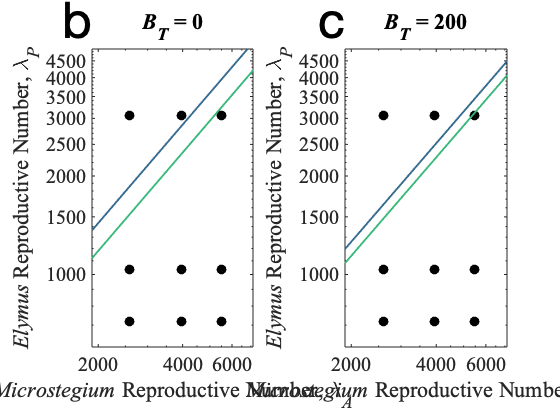

colors = viridis(4);    %Defining colors to plot the lines
colors = colors(2:3,:); %Defining colors to plot the lines

% Values of decomposition and tree litterfall to use in the panels.
dvec = 0.1*ones(1,2);  BTvec = [0,200];

% Values of relative sensitivity of Elymus to litter.
rel_den = [0.5, 1, 1.5];
% Differe line types for the different values of elymus relative density.
LTYPE = {'--', '-', ':'};
LABEL = {'b', 'c'};

figure()
t = tiledlayout(1,2);

% Loop over the four possible combinations of d and B_T
for k = 1:2
    
    % Set the values of d and BT
    d = dvec(k); BT = BTvec(k);
   
    nexttile
    
    % Create axes
    loglog(0,0,'Color','none', 'HandleVisibility','off');
    xlabel('{\itMicrostegium} Reproductive Number, \lambda_{\itA}');
    ylabel('{\itElymus} Reproductive Number, \lambda_{\itP}')
    hold on
    % Plot the estimates of lambda_A and lambda_P
    for i = 1:length(lambdaA)
        scatter(lambdaA(i)*ones(1,length(lambdaP)), lambdaP,...
            100, 'filled', 'CData', zeros(1,3))
    end
    hold off
    set(gca, 'FontSize', 20); set(gca, 'FontName', 'Times New Roman');
    axis([1900, 1.3*max(lambdaA), 600, 1.6*max(lambdaP)])

    % Define a vector of values of lambda to create lines
    lambda_vec = linspace(0,10*lambda_max, 1000);
    
    %% Plot elymus invasion boundary
    hold on
    % Loop over the three values of elymus relative density
    
    for i = 2
     
        % Calculate the density of litter produced by microstegium at equilbirium
        Leq_A = LitterEq(lambda_vec, (lambda_vec-1)/micro_density, 1*betaA, bA/d, BT);
        % Find the critical values of elymus lambda required to invade.
        lambda_P_crit = lambda_vec.*(1+rel_den(i)*betaP*Leq_A)./(1+betaA*Leq_A);
        % Plot this line
        loglog(lambda_vec, lambda_P_crit, LTYPE{i}, 'Color', colors(2,:),...
            'LineWidth', 2);
    
        % Now do the same for the invasion boundary of microstegium
        % Calculate elymus competition coefficient with relative density
        % value
        alphaPprime = (lambda_vec - 1).*(1+(1-mean(p2))./mean(p1))/(elymus_density);
        % Calculate eq litter produced by elymus as resident
        Leq_P = LitterEq(lambda_vec, alphaPprime, betaP*rel_den(i), bP/d, BT);
        % Calculate critical values of lambda needed for Microstegium to
        % invade
        lambda_A_crit = lambda_vec.*(1+betaA*Leq_P)./(1+rel_den(i)*betaP*Leq_P);
        % Plot these critical invasion values 
        loglog(lambda_A_crit, lambda_vec, LTYPE{i}, 'Color', colors(1,:),...
            'LineWidth', 2)
    end
    hold off
    % Label the plot
    title(['{\itB_T} = ', num2str(BT)]);
    t = text(0,1,LABEL{k}, 'Units', 'Normalized', 'HorizontalAlignment', 'right');
    t.FontSize = 50;
    t.VerticalAlignment = 'bottom';
end

References Cited

Ash, A. N. 1995. Effects of clear-cutting on litter parameters in the southern Blue Ridge Mountains. Castanea 60:89–97.

DeMeester, J. E., and D. D. Richter. 2010. Differences in wetland nitrogen cycling between the invasive grass Microstegium vimineum and a diverse plant community. Ecological Applications 20:609–619.

Emery, S. M., S. Luke Flory, K. Clay, J. R. Robb, and B. Winters. 2013. Demographic responses of the invasive annual grass Microstegium vimineum to prescribed fires and herbicide. Forest Ecology and Management 308:207–213.

Garrison, M. A., and J. C. Stier. 2010. Cool-season turfgrass colony and seed survival in a restored prairie. Crop Science 50:345–356.

Lauenroth, W. K., and P. B. Adler. 2008. Demography of perennial grassland plants: Survival, life expectancy and life span. Journal of Ecology 96:1023–1032.

Redwood, M. E., G. R. Matlack, and C. D. Huebner. 2018. Seed longevity and dormancy state suggest management strategies for garlic mustard (Alliaria petiolata) and Japanese stiltgrass (Microstegium vimineum) in deciduous forest sites. Weed Science 66:190–198.

Reynolds, S. A., J. D. Corbin, and C. M. D’Antonio. 2001. The effects of litter and temperature on the germination of native and exotic grasses in a coastal California grassland. Madrono 48:230–235.

Stevens, O. A. 1957. Weights of seeds and numbers per plant. Weeds 5:46–55.

Warren, R. J., V. Bahn, and M. A. Bradford. 2013. Decoupling litter barrier and soil moisture influences on the establishment of an invasive grass. Plant and Soil 367:339–346.

Wilson, C. H., T. T. Caughlin, D. J. Civitello, and S. L. Flory. 2015. Combining mesocosm and field experiments to predict invasive plant performance: A hierarchical Bayesian approach. Ecology 96:1084–1092.